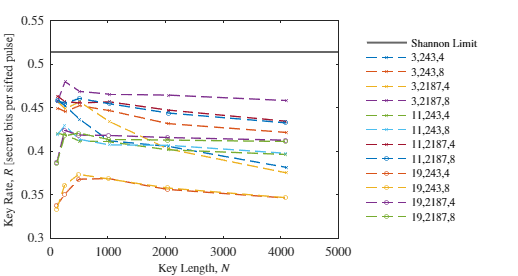

A = readtable("..\mb,q=3,agg.csv");
q=3;
p_err=0.01;
success_rate=0.9;
block_length=[3, 11, 19];
list_size=[243,2187];
max_num_indices_to_encode=[4, 8];
tol = 5 * eps(100); % A very small value
B = A(ismembertol(A.q, q, tol) & ...
    ismembertol(A.p_err, p_err, tol) & ...
    A.N < 8000 & ...
    ismembertol(A.mb_desired_success_rate, success_rate, tol) & ...
    ismembertol(A.mb_block_length(:), block_length, tol) & ...
    ismembertol(A.list_size(:), list_size, tol) & ...
    ismembertol(A.mb_max_num_indices_to_encode(:), max_num_indices_to_encode, tol), :);
T = table(B.mb_block_length(:), B.list_size(:), B.mb_max_num_indices_to_encode);
G = findgroups(T);
group_names = string(B.mb_block_length) + ',' + string(B.list_size) + ',' + string(B.mb_max_num_indices_to_encode);

f = figure;
f.Units = 'inches';
f.Position(3:4) = 1.2*[4.5 2.4];
ax = axes(); 
ax.LineStyleOrder = {'--x','--o', '--^', '--*'};
hold on
yline(B.theoretic_key_rate(1), 'DisplayName', 'Shannon Limit','LineWidth', 1.5);
splitapply(@plot_ir, B.N(:), B.key_rate_success_only(:), group_names(:), G(:))
xlabel("Key Length, $N$",'Interpreter','latex','FontSize', 9);
ylabel("Key Rate, $R$ [secret bits per sifted pulse]",'Interpreter','latex','FontSize', 9) 
box on
legend('boxoff');
legend('Interpreter','latex','FontSize', 8);
legend('Location','eastoutside');
f.CurrentAxes.TickLabelInterpreter = 'latex';
hold off

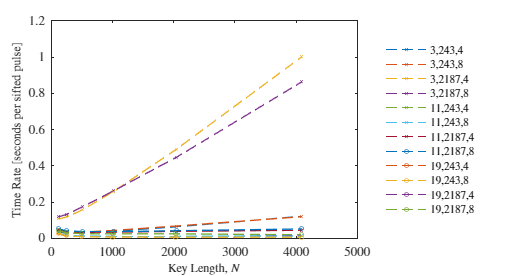


f = figure;
f.Units = 'inches';
f.Position(3:4) = 1.2*[4.5 2.4];
ax = axes(); 
ax.LineStyleOrder = {'--x','--o', '--^', '--*'};
hold on
splitapply(@plot_ir, B.N(:), B.time_rate(:), group_names(:), G(:))
xlabel("Key Length, $N$",'Interpreter','latex','FontSize', 9);
ylabel("Time Rate [seconds per sifted pulse]",'Interpreter','latex','FontSize', 9);
box on
legend('boxoff');
legend('Interpreter','latex','FontSize', 8);
legend('Location','eastoutside');
f.CurrentAxes.TickLabelInterpreter = 'latex';
legend
hold off

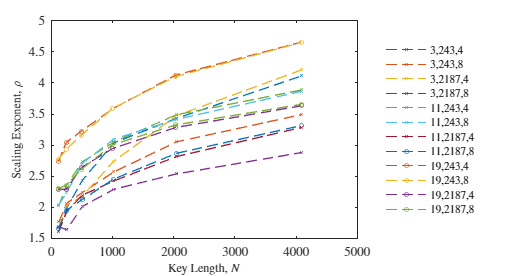


f = figure;
f.Units = 'inches';
f.Position(3:4) = 1.2*[4.5 2.4];
ax = axes(); 
ax.LineStyleOrder = {'--x','--o', '--^', '--*'};
gap = B.theoretic_key_rate - B.key_rate_success_only;
scaling_exponent = -log(B.N) ./ log(gap);
hold on
splitapply(@plot_ir, B.N(:), scaling_exponent(:), group_names(:), G(:))
xlabel("Key Length, $N$",'Interpreter','latex','FontSize', 9);
ylabel("Scaling Exponent, $\rho$",'Interpreter','latex','FontSize', 9);
box on
legend('boxoff');
legend('Interpreter','latex','FontSize', 8);
legend('Location','eastoutside');
f.CurrentAxes.TickLabelInterpreter = 'latex';
legend
hold off

function plot_ir(x, y, name)
    plot(x, y, 'DisplayName', name(1), 'MarkerSize', 3)
end